addpath masks\
addpath test_code\
addpath images\testImages\

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TO-DO:
% - CROP IMAGE BEFORE IT PROCESSES IT THROUGHT THE MASK
% - IS THERE 2 FOUND MASKS
% - IF SO FIND DISTANCE BETWEEN THEM AND DETERMINE IF A WAYPOINT OR NOT

clear payloadMask
% Mask image to look for Dock
    [payloadMask,payloadImage] = payloadMask(payload);
    
    % Clean image and find centroids
    se = strel('disk',5);
    
    cleanPayload = imopen(payloadMask, se);
    targetPayload = regionprops(cleanPayload,'centroid');
    
    % Place coordinates into array, [0 0] if no centroid
    centroidsPayload = cat(1,targetPayload.Centroid);
    if isempty(centroidsPayload)                       % if no target found
        centroidsPayload = [0 0];                      % place centroids at the center
    end

    % Find area of centroids and place into array, if none [0 0]
    targetAreaPayload = regionprops(cleanPayload,'area');
    areasPayload = cat(1,targetAreaPayload.Area);
    if isempty(areasPayload)
       areasPayload = [0 0]; 
    end
    
    % Find biggest centroid and save coordinates
    results = zeros(1,2)

results =      0     0


    [valPayload, idxPayload] = max(areasPayload);
        if isempty(idxPayload)
            results(1,:) = [0 0];
            curve = createBellCurve(-1);
            %reached = 0;
        else    
            results(1,:) = centroidsPayload(idxPayload,:);
            curve = createBellCurve(results(1,2)*(3/16));
            %reached = 1
        end
    

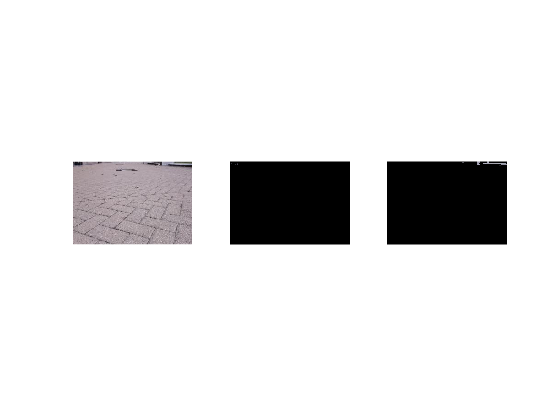

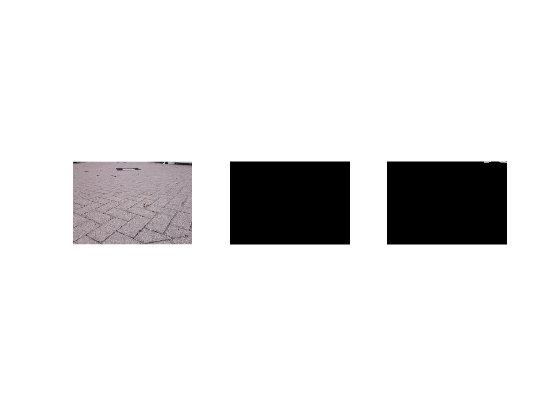

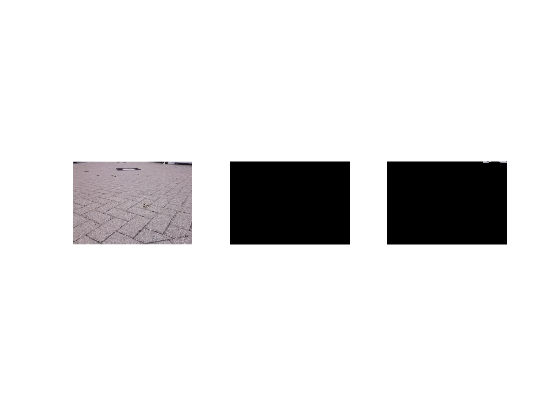

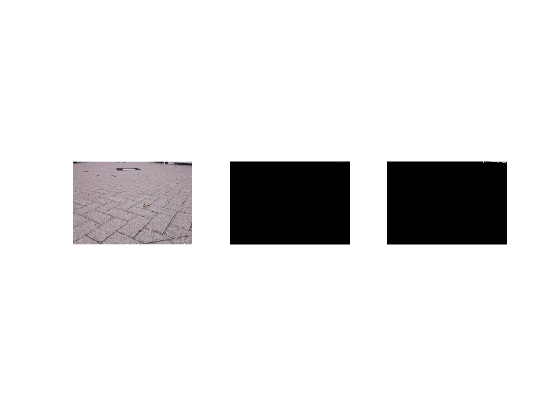

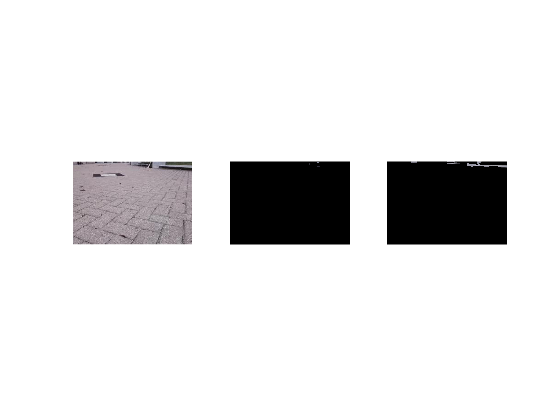

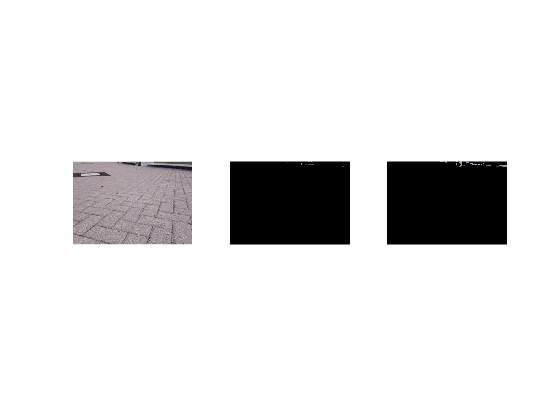

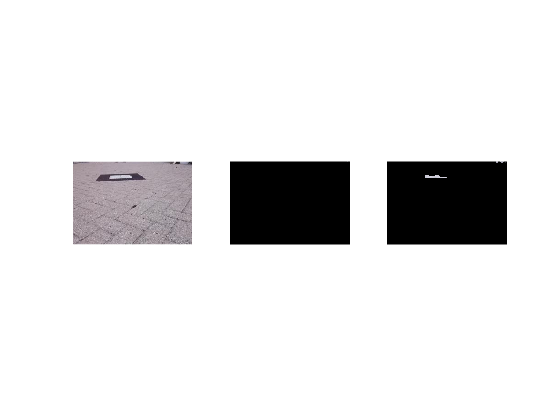

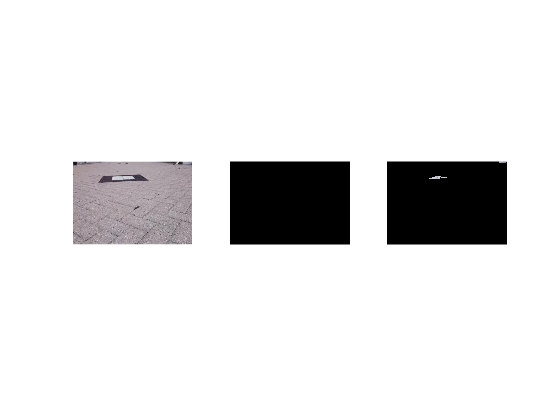

% Test masks for accuracy
images = cell(84,1);
for i = 1:84
    images{i} = imread(sprintf('images/testImages/img%d.jpg', i));
    if i < 85
        images{i} = images{i}(61:240,31:290,:);
    else
        images{i} = images{i}(140:end,:,:);
    end
end

resultsOut = zeros(84,2);
resultsInn = zeros(84,2);

for i = 1:84
    % Mask being tested
    [outerMask, testImageOut] = OuterMask(images{i});
    [innerMask, testImageInn] = newHSVInnerMask(images{i});
    
    % to remove any disk with radius < 5 pixels
    se = strel('disk',5);
    
    % clean mask of smaller centroids and cat location of centroids to an array
    cleanOuter = imopen(outerMask,se);
    cleanInner = imopen(innerMask,se);
    targetOuter = regionprops(cleanOuter,'centroid');
    targetInner = regionprops(cleanInner,'centroid');
    outerCentroids = cat(1,targetOuter.Centroid);
        if isempty(outerCentroids)
            outerCentroids = [0,0];
        end
    innerCentroids = cat(1,targetInner.Centroid);
        if isempty(innerCentroids)
            innerCentroids = [0,0];
        end
    
    % find the area of each present centroid
    targetAreaOuter = regionprops(cleanOuter, 'area');
    targetAreaInner = regionprops(cleanInner, 'area');
    areaOuter = cell2mat(struct2cell(targetAreaOuter));
        if isempty(targetAreaOuter)              %if no target found
            areaOuter = 0;                       % place centroids at 0 0
        end
    areaInner = cell2mat(struct2cell(targetAreaInner));
        if isempty(targetAreaInner)
            areaInner = 0;
        end
    
    
    %Find the biggest centroid and only return that coordinate
    [valOut,idxOut] = max(areaOuter);
    resultsOut(i,:) = outerCentroids(idxOut,:);
    [valInn,idxInn] = max(areaInner);
    resultsInn(i,:) = innerCentroids(idxInn,:);
    
    results = [resultsOut,resultsInn];
    
    % plot testImage and centroid on top of that
    figure(i)
    subplot(1,3,1)
    imshow(images{i})
    hold on
    plot(resultsOut(i,1), resultsOut(i,2), 'b*')
    plot(resultsInn(i,1), resultsInn(i,2), 'bo')
    hold off
    subplot(1,3,2)
    imshow(testImageOut)
    hold on
    plot(resultsOut(i,1), resultsOut(i,2), 'b*')
    plot(resultsInn(i,1), resultsInn(i,2), 'bo')
    hold off
    subplot(1,3,3)
    imshow(testImageInn)
    hold on
    plot(resultsOut(i,1), resultsOut(i,2), 'b*')
    plot(resultsInn(i,1), resultsInn(i,2), 'bo')
    hold off
      
end


counter = 0;
noMaskInn = zeros(84,1);
for i=1:84
    if resultsInn(i,1) == 0
        counter = counter + 1;
        noMaskInn(i,1) = 1;
    end
end
resultsInnAcc = ((84-counter)*100)/84

resultsInnAcc = 22.6190

resultsInnError = ((resultsInnAcc/100 - (35/84))/(35/84)) *100

resultsInnError = -45.7143

counter = 0;
noMaskOut = zeros(84,1);
for i=1:84
    if resultsOut(i,1) == 0
        counter = counter + 1;
        noMaskOut(i,1) = 1;
    end
end
resultsOutAcc = ((84-counter)*100)/84

resultsOutAcc = 22.6190

resultsOutError = ((resultsOutAcc/100 - (35/84))/(35/84)) *100

resultsOutError = -45.7143

%img12 = img12(61:240,31:290,:);
% Mask being tested
    [outerMask, testImageOut] = newHSVOuterMask(img12);
    [innerMask, testImageInn] = newHSVInnerMask(img12);
    
    % clean mask of smaller centroids and cat location of centroids to an array
    se = strel('disk',5);
    
    cleanOuter = imopen(outerMask, se);
    targetOuter = regionprops(cleanOuter,'centroid');
    %centroidsOuter = cell2mat(struct2cell(targetOuter)); 
    centroidsOuter = cat(1,targetOuter.Centroid);
    if isempty(centroidsOuter)                       % if no target found
        centroidsOuter = [121 161];                      % place centroids at the center
    end
    
    cleanCenter = imopen(innerMask, se);
    targetCenter = regionprops(cleanCenter,'centroid');
    %centroidsCenter = cell2mat(struct2cell(targetCenter));
    centroidsCenter = cat(1,targetCenter.Centroid);
    if isempty(centroidsCenter)                       % if no target found
        centroidsCenter = [121 161];                      % place centroids at the center
    end
    

    % Find area to determine biggest centroid
    targetAreaOuter = regionprops(cleanOuter, 'area');
    areaOuter = cell2mat(struct2cell(targetAreaOuter));
        if isempty(areaOuter)              %if no target found
            areaOuter = [0 0];                       % place centroids at 0 0
        end
    targetAreaCenter = regionprops(cleanCenter, 'area');
    areaInner = cell2mat(struct2cell(targetAreaCenter));
        if isempty(areaInner)              %if no target found
            areaInner = [0 0];                       % place centroids at 0 0
        end
        
    %Find the biggest centroid that is closest to the center and return that coordinate
    results = zeros(1,2);
    resultsOut = zeros(1,2);
    resultsInn = zeros(1,2);
    
    [valOuter,idxOuter] = max(areaOuter);
        if isempty(idxOuter)
            resultsOut(1,:) = [121 161];
        else    
            resultsOut(1,:) = centroidsOuter(:,idxOuter);
        end

    [valInner,idxInner] = max(areaInner);
        if isempty(idxInner)
            resultsInn(1,:) = [121 161];
        else
            resultsInn(1,:) = centroidsCenter(idxInner,:);
        end    
    
    % Determine which centroid to follow
    if abs(161 - resultsOut(1,2)) <= abs(161 - resultsInn(1,2))
        results(1,:) = resultsOut(1,:);
    else 
        results(1,:) = resultsInn(1,:);
    end